# **PHYS 371 Term-Project:**

# **THE VARIATIONAL-RELAXATION ALGORITHM FOR FINDING QUANTUM BOUND STATES.**

**Name: Shaig Khankishizade**

**ID: 21701200**

**Department: Physics**

## Introduction and Information about algorithm:

Relaxation algorithm is a discretized iterative method that solves Poisson's equation in 2 dimensions numerically as it is not generally possible to solve it analytically. Thus, this project aims to solve the Shrodinger's equation in 2 dimension in form of:

$\Delta \psi(r) =-2(E-V(r))\psi(r)$ where $\Delta$ is a Laplacian operator.

Furthermore, making the Laplacian discrete we can write it as:

$\psi_0=\bar{\psi_{nn}}+\frac{1}{d}(E-V_{0})\psi_0\delta^2$ or $\psi_0=\frac{\bar{\psi_{nn}}}{1-(E-V_0)\delta^2/d}$ where d is dimension number which is 2 in this case. and $\bar{\psi_{nn}}$ is average of the values of points neighbouring grid points in y and x direction.

We can write energy asn an expectation value in discrete form as :

$\left\langle E \right\rangle = \frac{\left\langle \psi | H | \psi \right\rangle}{\left\langle \psi | \psi \right\rangle}$ where H is Hamiltonian $\left\langle \psi | H | \psi \right\rangle = \left\langle \psi | K | \psi \right\rangle - \left\langle \psi | V_0 | \psi \right\rangle = -4\bar{\psi_{nn}}(\psi_{0,new}-\psi_{0,old})+2(\psi^2_{0,new}-\psi^2_{0,old})-V_0\frac{1}{n^2}(\psi^2_{0,new}-\psi^2_{0,old}) + SUM$

and $\left\langle \psi | \psi \right\rangle = (\psi^2_{0,new}-\psi^2_{0,old})\frac{1}{n^2} + SUM$

Here $\frac{1}{n^2}$ acts as a dx in one dimension. here it serves as small lattice spacing in grid or as $\delta^2$.

Now since we have value of $\left\langle E \right\rangle$, we can write Wave function in terms of it:


$$\psi_0=\frac{\bar{\psi_{nn}}}{1-(\left\langle E \right\rangle-V_0)\frac{1}{2n^2}}$$
 

Thus, this equation will give value of only one point on grid, we should go over all points except the boundary points, they are 0 and should remain like that there fore we should start from the 2nd point on grid.

We must repeat going all over the grid continuously as it converges to the point where Expectation value of Energy does not change. And in order to speed that process up we use **over-relaxtion **method with $\omega=1.8$; So, when we are on certain point on a grid we update that point using new formula:

$\psi_{0,nominal}=\frac{\bar{\psi_{nn}}}{1-(\left\langle E \right\rangle-V_0)\frac{1}{2n^2}}$  and $\psi_{0,new}=\psi_{0,old}+\omega(\psi_{0,nominal}-\psi_{0,old})$ 

So, now in about 20 or little more iterations Energy converges.

## Initial wavefunctions and finding excited states:

Since wavefunctions are in 2D we define as 2 sinus functions in x and y directions with $n_x$ and $n_y$:

$\psi_{n_x,n_y}=\frac{2}{N}\sin{(\frac{n_x\pi x}{N})}\sin{(\frac{n_y\pi y}{N})}$ where N is the discreet length of N by N grid. We require first 3 excited states and a ground state ( $\psi_{1,1}$, $\psi_{2,1}$, $\psi_{1,2}$, $\psi_{2,2}$ ).

But we should consider one thing that we should subtract the contribution of states lower that the state that we are iterating. And in order to realize that we should take inner product of wavefunction with the previous states and subtract from the state that is being iterated. In other words or in formula:

$\psi_2 = \psi_2 - \left\langle \psi_1 | \psi_2 \right\rangle \psi_1$ (For example, here $\psi_2$ is iterated state and $\psi_1$ is a lower state and so its contribution should be subtracted).

And after this operation before iteration ends, $\left\langle \psi_2 | H | \psi _2\right\rangle$ and $\left\langle \psi_2 | \psi_2 \right\rangle$ should be recalculated.

## Things that need to be considered:

We should consider that without any potential surface or barrier this algorithm grid acts as a infinite square well, which means that if we want to impose a potential surface the variations in potential values should be little far away from the boundaries so the system can act as a infinitely wide sheet or space.

## Itinery of this Project:

- **Producing a Potential surface with a form of "Bilkent-B".**

- **Superimposing the wavefunction to Bilkent-B Potential surface with mesh plotting first 3 states.**

- **Building an application that demonstrates contour plots of ground state and first 3 excited states and their Energies on circular potential surface. Furthermore, creating an interactive option to make variations in properties of Circular potential barrier such as: changing radius, height of the barrier and inverting the barrier.**

## Producing a Potential surface with a form of "Bilkent-B"

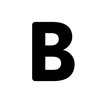 101x101 B image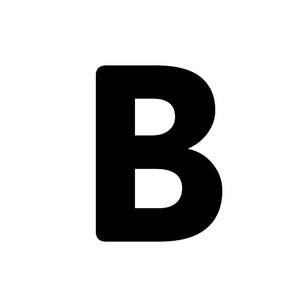 301x301 B image

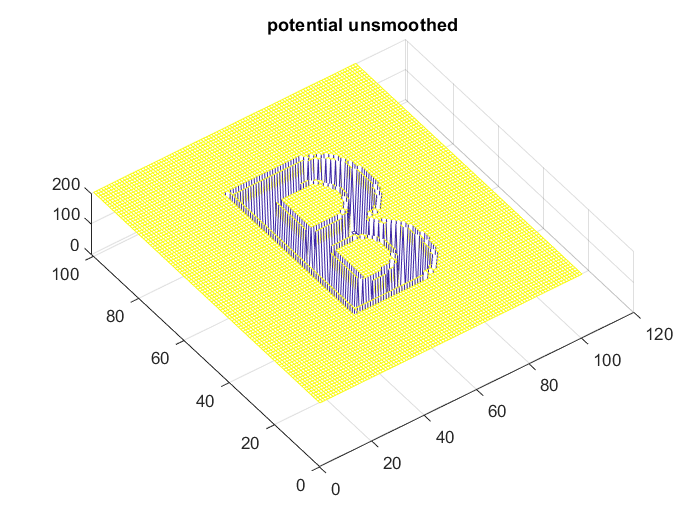

N=100;
n=0:N;
[X Y]=meshgrid(n);
%by importing a data of a PNG image which is 100 by 100
v = imread('100_bb.png');
v=v(:,:,1);
%giving values to black pixels and white pixels in data
find(v~=0);
v(ans)=200;
find(v==0);
v(ans)=0;
v=double(v);
%plotting
figure(1)
mesh(v);title('potential unsmoothed');
view([-36 77])

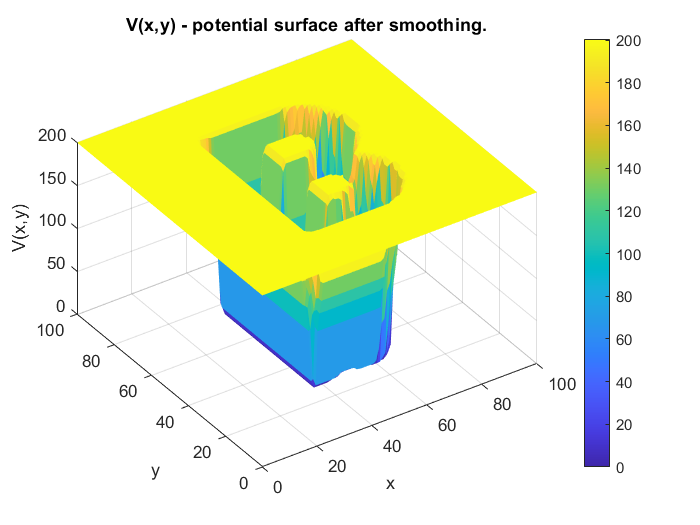

%smoothing with savitzky-golay filter by taking vertical lines and
%horizontal lines on grid. Also additionally smoothing edges of sgolay again with
%median filter.
for i=1:(N+1)
    l=v(:,i);
    t=0:(length(l)-1);
    nineMA = sgolayfilt(l, 5, 7);
    yMedFilt = medfilt1(nineMA,5,'truncate');
    v(:,i)=yMedFilt;
end

for i=2:(N)
    l=v(i,:);
    t=0:(length(l)-1);
    nineMA = sgolayfilt(l, 7, 9);
    yMedFilt = medfilt1(nineMA,5,'truncate');
    v(i,:)=yMedFilt;
end
% if there are still pikes on the edges below 0, making those points 0.
ind=find(v<0);
v(ind)=0;

%plotting smoothed potential surface
figure(2)
C = v;
surf(X,Y,v,C); 
shading flat
colorbar;
view([-34 47])
title('V(x,y) - potential surface after smoothing.');xlabel('x');ylabel('y');zlabel('V(x,y)');

## Superimposing wave function to Potential surface with Relaxation algorithm:

clc;clf
N=100;
% by using wavefunc getting all initial few states with their expectation
% energies in one line and recording the run time. ( it is aound 1.5
% seconds in .m format)
tic
[exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefunc(v,N);
toc

Elapsed time is 17.028265 seconds.


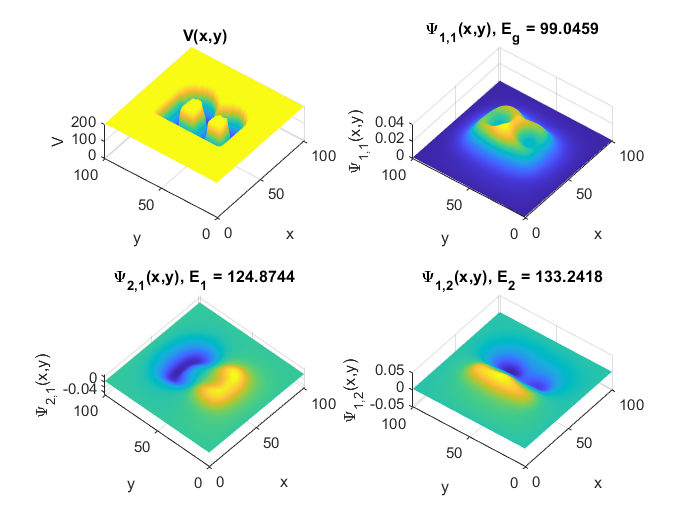


figure(3)
subplot(2,2,1)
surf(v)
shading interp
view([-52.194 70.873])
title('V(x,y)');xlabel('x');ylabel('y');zlabel('V');
subplot(2,2,2)
surf(F_psin)
shading interp
view([-52.194 70.873])
title(['\Psi_{1,1}(x,y), E_g = ' num2str(exEn)]);xlabel('x');ylabel('y');zlabel('\Psi_{1,1}(x,y)');
subplot(2,2,3)
surf(F_psi1)
shading interp
view([-47.682 79.249])
title(['\Psi_{2,1}(x,y), E_1 = ' num2str(exE1)]);xlabel('x');ylabel('y');zlabel('\Psi_{2,1}(x,y)');
subplot(2,2,4)
surf(F_psi2)
shading interp
view([-52.194 70.873])
title(['\Psi_{1,2}(x,y), E_2 = ' num2str(exE2)]);xlabel('x');ylabel('y');zlabel('\Psi_{1,2}(x,y)');

## Finding the first few excited states of circular potential and their expectation Energies (APP):

classdef Circ_pot_prog_e < matlab.apps.AppBase

    % Properties that correspond to app components
    properties (Access = public)
        UIFigure                      matlab.ui.Figure
        GridLayout                    matlab.ui.container.GridLayout
        LeftPanel                     matlab.ui.container.Panel
        UIAxes                        matlab.ui.control.UIAxes
        RadiusSliderLabel             matlab.ui.control.Label
        RadiusSlider                  matlab.ui.control.Slider
        PotentialStrengthSliderLabel  matlab.ui.control.Label
        PotentialStrengthSlider       matlab.ui.control.Slider
        CircularPotentialLabel        matlab.ui.control.Label
        InvertCheckBox                matlab.ui.control.CheckBox
        PotentialStrengthEditFieldLabel  matlab.ui.control.Label
        PotentialStrengthEditField    matlab.ui.control.NumericEditField
        InfoWhitecolourindicatesthefieldwithzeropotentialLabel  matlab.ui.control.Label
        RightPanel                    matlab.ui.container.Panel
        UIAxes_2                      matlab.ui.control.UIAxes
        UIAxes_3                      matlab.ui.control.UIAxes
        UIAxes_4                      matlab.ui.control.UIAxes
        UIAxes_5                      matlab.ui.control.UIAxes
        DWavefunctionStatesLabel      matlab.ui.control.Label
        GroundstateEnergyEditFieldLabel  matlab.ui.control.Label
        GroundstateEnergyEditField    matlab.ui.control.NumericEditField
        FirstexcitedstateEnergyEditFieldLabel  matlab.ui.control.Label
        FirstexcitedstateEnergyEditField  matlab.ui.control.NumericEditField
        SecondexcitedstateEnergyEditFieldLabel  matlab.ui.control.Label
        SecondexcitedstateEnergyEditField  matlab.ui.control.NumericEditField
        ThirdexcitedstateEnergyEditFieldLabel  matlab.ui.control.Label
        ThirdexcitedstateEnergyEditField  matlab.ui.control.NumericEditField
        StartButton                   matlab.ui.control.Button
        Label                         matlab.ui.control.Label
    end

    % Properties that correspond to apps with auto-reflow
    properties (Access = private)
        onePanelWidth = 576;
    end

    
    properties (Access = private)
        N=100; %fixed N by N grid
    end
    

    % Callbacks that handle component events
    methods (Access = private)

        % Value changed function: RadiusSlider
        function RadiusSliderValueChanged(app, event)
            r = app.RadiusSlider.Value;
            
            if app.InvertCheckBox.Value==1
                Vc=circlepotential(r,app.N+1,app.PotentialStrengthSlider.Value);
            else
                Vc=circlepotential(r,app.N+1,-app.PotentialStrengthSlider.Value);
            end
            
            
            if app.InvertCheckBox.Value==1
                V=circlepotim(app.RadiusSlider.Value,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [1 1 1; 0 0 0]);
            else
                V=circlepotim(app.RadiusSlider.Value,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [0 0 0; 1 1 1]);
            end  
            
            
            %reaction to change by computing everything again by giving
            %values to all entities and graphs on GUI again
            if app.InvertCheckBox.Value==1
                [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefuncINV(Vc,app.N);
                app.GroundstateEnergyEditField.Value=exEn;
                app.FirstexcitedstateEnergyEditField.Value=exE1;
                app.SecondexcitedstateEnergyEditField.Value=exE2;
                app.ThirdexcitedstateEnergyEditField.Value=exE3;
                contourf(app.UIAxes_3,F_psin);
                contourf(app.UIAxes_4,F_psi1);
                contourf(app.UIAxes_2,F_psi2);
                contourf(app.UIAxes_5,F_psi3);
            else
                [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefunc(Vc,app.N);
                app.GroundstateEnergyEditField.Value=exEn;
                app.FirstexcitedstateEnergyEditField.Value=exE1;
                app.SecondexcitedstateEnergyEditField.Value=exE2;
                app.ThirdexcitedstateEnergyEditField.Value=exE3;
                contourf(app.UIAxes_3,F_psin);
                contourf(app.UIAxes_4,F_psi1);
                contourf(app.UIAxes_2,F_psi2);
                contourf(app.UIAxes_5,F_psi3);
            end
        end

        % Value changing function: RadiusSlider
        function RadiusSliderValueChanging(app, event)
            changingRadius = event.Value;
            
            
            if app.InvertCheckBox.Value==1
                V=circlepotim(changingRadius,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [1 1 1; 0 0 0]);
            else
                V=circlepotim(changingRadius,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [0 0 0; 1 1 1]);
            end 
        end

        % Value changed function: PotentialStrengthSlider
        function PotentialStrengthSliderValueChanged(app, event)
            V_max = app.PotentialStrengthSlider.Value;
            
            app.PotentialStrengthEditField.Value=V_max;
            
            if app.InvertCheckBox.Value==1
                Vc=circlepotential(app.RadiusSlider.Value,app.N+1,V_max);
            else
                Vc=circlepotential(app.RadiusSlider.Value,app.N+1,-V_max);
            end
            
            if app.InvertCheckBox.Value==1
                V=circlepotim(app.RadiusSlider.Value,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [1 1 1; 0 0 0]);
            else
                V=circlepotim(app.RadiusSlider.Value,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [0 0 0; 1 1 1]);
            end  
            
            
            %reaction to change by computing everything again by giving
            %values to all entities and graphs on GUI again
            if app.InvertCheckBox.Value==1
                [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefuncINV(Vc,app.N);
                app.GroundstateEnergyEditField.Value=exEn;
                app.FirstexcitedstateEnergyEditField.Value=exE1;
                app.SecondexcitedstateEnergyEditField.Value=exE2;
                app.ThirdexcitedstateEnergyEditField.Value=exE3;
                contourf(app.UIAxes_3,F_psin);
                contourf(app.UIAxes_4,F_psi1);
                contourf(app.UIAxes_2,F_psi2);
                contourf(app.UIAxes_5,F_psi3);
            else
                [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefunc(Vc,app.N);
                app.GroundstateEnergyEditField.Value=exEn;
                app.FirstexcitedstateEnergyEditField.Value=exE1;
                app.SecondexcitedstateEnergyEditField.Value=exE2;
                app.ThirdexcitedstateEnergyEditField.Value=exE3;
                contourf(app.UIAxes_3,F_psin);
                contourf(app.UIAxes_4,F_psi1);
                contourf(app.UIAxes_2,F_psi2);
                contourf(app.UIAxes_5,F_psi3);
            end
        end

        % Value changed function: InvertCheckBox
        function InvertCheckBoxValueChanged(app, event)
            Value = app.InvertCheckBox.Value;
            
            
            if Value==1
                Vc=circlepotential(app.RadiusSlider.Value,app.N+1,app.PotentialStrengthSlider.Value);
            else
                Vc=circlepotential(app.RadiusSlider.Value,app.N+1,-app.PotentialStrengthSlider.Value);
            end
            
            if Value==1
                V=circlepotim(app.RadiusSlider.Value,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [1 1 1; 0 0 0]);
            else
                V=circlepotim(app.RadiusSlider.Value,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [0 0 0; 1 1 1]);
            end  
            
            
            %reaction to change by computing everything again by giving
            %values to all entities and graphs on GUI again
            if app.InvertCheckBox.Value==1
                [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefuncINV(Vc,app.N);
                app.GroundstateEnergyEditField.Value=exEn;
                app.FirstexcitedstateEnergyEditField.Value=exE1;
                app.SecondexcitedstateEnergyEditField.Value=exE2;
                app.ThirdexcitedstateEnergyEditField.Value=exE3;
                contourf(app.UIAxes_3,F_psin);
                contourf(app.UIAxes_4,F_psi1);
                contourf(app.UIAxes_2,F_psi2);
                contourf(app.UIAxes_5,F_psi3);
            else
                [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefunc(Vc,app.N);
                app.GroundstateEnergyEditField.Value=exEn;
                app.FirstexcitedstateEnergyEditField.Value=exE1;
                app.SecondexcitedstateEnergyEditField.Value=exE2;
                app.ThirdexcitedstateEnergyEditField.Value=exE3;
                contourf(app.UIAxes_3,F_psin);
                contourf(app.UIAxes_4,F_psi1);
                contourf(app.UIAxes_2,F_psi2);
                contourf(app.UIAxes_5,F_psi3);
            end
        end

        % Button pushed function: StartButton
        function StartButtonPushed(app, event)
            
            app.PotentialStrengthEditField.Value=app.PotentialStrengthSlider.Value;
                 
            if app.InvertCheckBox.Value==1
                Vc=circlepotential(app.RadiusSlider.Value,app.N+1,app.PotentialStrengthSlider.Value);
            else
                Vc=circlepotential(app.RadiusSlider.Value,app.N+1,-app.PotentialStrengthSlider.Value);
            end
            
            if app.InvertCheckBox.Value==1
                V=circlepotim(app.RadiusSlider.Value,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [1 1 1; 0 0 0]);
            else
                V=circlepotim(app.RadiusSlider.Value,app.N+1);
                imshow(V,'Parent',app.UIAxes);
                colormap(app.UIAxes, [0 0 0; 1 1 1]);
            end 
            
            
            if app.InvertCheckBox.Value==1
                [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefuncINV(Vc,app.N);
                app.GroundstateEnergyEditField.Value=exEn;
                app.FirstexcitedstateEnergyEditField.Value=exE1;
                app.SecondexcitedstateEnergyEditField.Value=exE2;
                app.ThirdexcitedstateEnergyEditField.Value=exE3;
                contourf(app.UIAxes_3,F_psin);
                contourf(app.UIAxes_4,F_psi1);
                contourf(app.UIAxes_2,F_psi2);
                contourf(app.UIAxes_5,F_psi3);
            else
                [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefunc(Vc,app.N);
                app.GroundstateEnergyEditField.Value=exEn;
                app.FirstexcitedstateEnergyEditField.Value=exE1;
                app.SecondexcitedstateEnergyEditField.Value=exE2;
                app.ThirdexcitedstateEnergyEditField.Value=exE3;
                contourf(app.UIAxes_3,F_psin);
                contourf(app.UIAxes_4,F_psi1);
                contourf(app.UIAxes_2,F_psi2);
                contourf(app.UIAxes_5,F_psi3);
            end
        end

        % Value changing function: PotentialStrengthSlider
        function PotentialStrengthSliderValueChanging(app, event)
            changingValue = event.Value;
             app.PotentialStrengthEditField.Value=changingValue;
        end

        % Changes arrangement of the app based on UIFigure width
        function updateAppLayout(app, event)
            currentFigureWidth = app.UIFigure.Position(3);
            if(currentFigureWidth <= app.onePanelWidth)
                % Change to a 2x1 grid
                app.GridLayout.RowHeight = {731, 731};
                app.GridLayout.ColumnWidth = {'1x'};
                app.RightPanel.Layout.Row = 2;
                app.RightPanel.Layout.Column = 1;
            else
                % Change to a 1x2 grid
                app.GridLayout.RowHeight = {'1x'};
                app.GridLayout.ColumnWidth = {435, '1x'};
                app.RightPanel.Layout.Row = 1;
                app.RightPanel.Layout.Column = 2;
            end
        end
    end

    % Component initialization
    methods (Access = private)

        % Create UIFigure and components
        function createComponents(app)

            % Create UIFigure and hide until all components are created
            app.UIFigure = uifigure('Visible', 'off');
            app.UIFigure.AutoResizeChildren = 'off';
            app.UIFigure.Position = [100 100 1229 731];
            app.UIFigure.Name = 'UI Figure';
            app.UIFigure.SizeChangedFcn = createCallbackFcn(app, @updateAppLayout, true);

            % Create GridLayout
            app.GridLayout = uigridlayout(app.UIFigure);
            app.GridLayout.ColumnWidth = {435, '1x'};
            app.GridLayout.RowHeight = {'1x'};
            app.GridLayout.ColumnSpacing = 0;
            app.GridLayout.RowSpacing = 0;
            app.GridLayout.Padding = [0 0 0 0];
            app.GridLayout.Scrollable = 'on';

            % Create LeftPanel
            app.LeftPanel = uipanel(app.GridLayout);
            app.LeftPanel.Layout.Row = 1;
            app.LeftPanel.Layout.Column = 1;

            % Create UIAxes
            app.UIAxes = uiaxes(app.LeftPanel);
            title(app.UIAxes, 'Circular Potential Well')
            xlabel(app.UIAxes, '')
            ylabel(app.UIAxes, '')
            app.UIAxes.XTick = [];
            app.UIAxes.YTick = [];
            app.UIAxes.Position = [91 393 253 234];

            % Create RadiusSliderLabel
            app.RadiusSliderLabel = uilabel(app.LeftPanel);
            app.RadiusSliderLabel.HorizontalAlignment = 'right';
            app.RadiusSliderLabel.FontWeight = 'bold';
            app.RadiusSliderLabel.Position = [40 41 45 22];
            app.RadiusSliderLabel.Text = 'Radius';

            % Create RadiusSlider
            app.RadiusSlider = uislider(app.LeftPanel);
            app.RadiusSlider.Limits = [0 40];
            app.RadiusSlider.MajorTicks = [0 5 10 15 20 25 30 35 40];
            app.RadiusSlider.Orientation = 'vertical';
            app.RadiusSlider.ValueChangedFcn = createCallbackFcn(app, @RadiusSliderValueChanged, true);
            app.RadiusSlider.ValueChangingFcn = createCallbackFcn(app, @RadiusSliderValueChanging, true);
            app.RadiusSlider.MinorTicks = [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40];
            app.RadiusSlider.FontWeight = 'bold';
            app.RadiusSlider.Position = [103 50 3 257];
            app.RadiusSlider.Value = 10;

            % Create PotentialStrengthSliderLabel
            app.PotentialStrengthSliderLabel = uilabel(app.LeftPanel);
            app.PotentialStrengthSliderLabel.HorizontalAlignment = 'right';
            app.PotentialStrengthSliderLabel.FontWeight = 'bold';
            app.PotentialStrengthSliderLabel.Position = [213 41 109 22];
            app.PotentialStrengthSliderLabel.Text = 'Potential Strength';

            % Create PotentialStrengthSlider
            app.PotentialStrengthSlider = uislider(app.LeftPanel);
            app.PotentialStrengthSlider.Limits = [0 200];
            app.PotentialStrengthSlider.MajorTicks = [0 20 40 60 80 100 120 140 160 180 200];
            app.PotentialStrengthSlider.Orientation = 'vertical';
            app.PotentialStrengthSlider.ValueChangedFcn = createCallbackFcn(app, @PotentialStrengthSliderValueChanged, true);
            app.PotentialStrengthSlider.ValueChangingFcn = createCallbackFcn(app, @PotentialStrengthSliderValueChanging, true);
            app.PotentialStrengthSlider.FontWeight = 'bold';
            app.PotentialStrengthSlider.Position = [343 50 3 257];
            app.PotentialStrengthSlider.Value = 100;

            % Create CircularPotentialLabel
            app.CircularPotentialLabel = uilabel(app.LeftPanel);
            app.CircularPotentialLabel.FontSize = 36;
            app.CircularPotentialLabel.FontWeight = 'bold';
            app.CircularPotentialLabel.FontColor = [0.6392 0.1412 0.1412];
            app.CircularPotentialLabel.Position = [79 653 307 46];
            app.CircularPotentialLabel.Text = 'Circular Potential';

            % Create InvertCheckBox
            app.InvertCheckBox = uicheckbox(app.LeftPanel);
            app.InvertCheckBox.ValueChangedFcn = createCallbackFcn(app, @InvertCheckBoxValueChanged, true);
            app.InvertCheckBox.Text = 'Invert';
            app.InvertCheckBox.Position = [53 335 86 26];

            % Create PotentialStrengthEditFieldLabel
            app.PotentialStrengthEditFieldLabel = uilabel(app.LeftPanel);
            app.PotentialStrengthEditFieldLabel.HorizontalAlignment = 'right';
            app.PotentialStrengthEditFieldLabel.Position = [171 337 100 22];
            app.PotentialStrengthEditFieldLabel.Text = 'Potential Strength';

            % Create PotentialStrengthEditField
            app.PotentialStrengthEditField = uieditfield(app.LeftPanel, 'numeric');
            app.PotentialStrengthEditField.Position = [286 337 100 22];

            % Create InfoWhitecolourindicatesthefieldwithzeropotentialLabel
            app.InfoWhitecolourindicatesthefieldwithzeropotentialLabel = uilabel(app.LeftPanel);
            app.InfoWhitecolourindicatesthefieldwithzeropotentialLabel.HorizontalAlignment = 'center';
            app.InfoWhitecolourindicatesthefieldwithzeropotentialLabel.VerticalAlignment = 'bottom';
            app.InfoWhitecolourindicatesthefieldwithzeropotentialLabel.FontSize = 11;
            app.InfoWhitecolourindicatesthefieldwithzeropotentialLabel.FontAngle = 'italic';
            app.InfoWhitecolourindicatesthefieldwithzeropotentialLabel.Position = [82 379 277 22];
            app.InfoWhitecolourindicatesthefieldwithzeropotentialLabel.Text = 'Info: White colour indicates the field with zero potential.';

            % Create RightPanel
            app.RightPanel = uipanel(app.GridLayout);
            app.RightPanel.BackgroundColor = [0.9412 0.9412 0.9412];
            app.RightPanel.Layout.Row = 1;
            app.RightPanel.Layout.Column = 2;

            % Create UIAxes_2
            app.UIAxes_2 = uiaxes(app.RightPanel);
            title(app.UIAxes_2, '\psi_{1,2}')
            xlabel(app.UIAxes_2, 'X')
            ylabel(app.UIAxes_2, 'Y')
            app.UIAxes_2.FontSize = 11;
            app.UIAxes_2.XTick = [];
            app.UIAxes_2.YTick = [];
            app.UIAxes_2.Position = [98 104 253 234];

            % Create UIAxes_3
            app.UIAxes_3 = uiaxes(app.RightPanel);
            title(app.UIAxes_3, '\psi_{1,1}')
            xlabel(app.UIAxes_3, 'X')
            ylabel(app.UIAxes_3, 'Y')
            app.UIAxes_3.FontSize = 11;
            app.UIAxes_3.XTick = [];
            app.UIAxes_3.YTick = [];
            app.UIAxes_3.Position = [99 385 253 234];

            % Create UIAxes_4
            app.UIAxes_4 = uiaxes(app.RightPanel);
            title(app.UIAxes_4, '\psi_{2,1}')
            xlabel(app.UIAxes_4, 'X')
            ylabel(app.UIAxes_4, 'Y')
            app.UIAxes_4.FontSize = 11;
            app.UIAxes_4.XTick = [];
            app.UIAxes_4.YTick = [];
            app.UIAxes_4.Position = [448 385 253 234];

            % Create UIAxes_5
            app.UIAxes_5 = uiaxes(app.RightPanel);
            title(app.UIAxes_5, '\psi_{2,2}')
            xlabel(app.UIAxes_5, 'X')
            ylabel(app.UIAxes_5, 'Y')
            app.UIAxes_5.XTick = [];
            app.UIAxes_5.YTick = [];
            app.UIAxes_5.Position = [447 104 253 234];

            % Create DWavefunctionStatesLabel
            app.DWavefunctionStatesLabel = uilabel(app.RightPanel);
            app.DWavefunctionStatesLabel.FontSize = 36;
            app.DWavefunctionStatesLabel.FontWeight = 'bold';
            app.DWavefunctionStatesLabel.FontColor = [0.3059 0.4392 0.1333];
            app.DWavefunctionStatesLabel.Position = [321 653 421 46];
            app.DWavefunctionStatesLabel.Text = '2D Wavefunction States';

            % Create GroundstateEnergyEditFieldLabel
            app.GroundstateEnergyEditFieldLabel = uilabel(app.RightPanel);
            app.GroundstateEnergyEditFieldLabel.HorizontalAlignment = 'right';
            app.GroundstateEnergyEditFieldLabel.Position = [121 358 117 22];
            app.GroundstateEnergyEditFieldLabel.Text = 'Ground state Energy';

            % Create GroundstateEnergyEditField
            app.GroundstateEnergyEditField = uieditfield(app.RightPanel, 'numeric');
            app.GroundstateEnergyEditField.Position = [253 358 100 22];

            % Create FirstexcitedstateEnergyEditFieldLabel
            app.FirstexcitedstateEnergyEditFieldLabel = uilabel(app.RightPanel);
            app.FirstexcitedstateEnergyEditFieldLabel.HorizontalAlignment = 'right';
            app.FirstexcitedstateEnergyEditFieldLabel.Position = [444 358 141 22];
            app.FirstexcitedstateEnergyEditFieldLabel.Text = 'First excited state Energy';

            % Create FirstexcitedstateEnergyEditField
            app.FirstexcitedstateEnergyEditField = uieditfield(app.RightPanel, 'numeric');
            app.FirstexcitedstateEnergyEditField.Position = [600 358 100 22];

            % Create SecondexcitedstateEnergyEditFieldLabel
            app.SecondexcitedstateEnergyEditFieldLabel = uilabel(app.RightPanel);
            app.SecondexcitedstateEnergyEditFieldLabel.HorizontalAlignment = 'right';
            app.SecondexcitedstateEnergyEditFieldLabel.Position = [78 62 158 22];
            app.SecondexcitedstateEnergyEditFieldLabel.Text = 'Second excited state Energy';

            % Create SecondexcitedstateEnergyEditField
            app.SecondexcitedstateEnergyEditField = uieditfield(app.RightPanel, 'numeric');
            app.SecondexcitedstateEnergyEditField.Position = [251 62 100 22];

            % Create ThirdexcitedstateEnergyEditFieldLabel
            app.ThirdexcitedstateEnergyEditFieldLabel = uilabel(app.RightPanel);
            app.ThirdexcitedstateEnergyEditFieldLabel.HorizontalAlignment = 'right';
            app.ThirdexcitedstateEnergyEditFieldLabel.Position = [441 62 145 22];
            app.ThirdexcitedstateEnergyEditFieldLabel.Text = 'Third excited state Energy';

            % Create ThirdexcitedstateEnergyEditField
            app.ThirdexcitedstateEnergyEditField = uieditfield(app.RightPanel, 'numeric');
            app.ThirdexcitedstateEnergyEditField.Position = [601 62 100 22];

            % Create StartButton
            app.StartButton = uibutton(app.RightPanel, 'push');
            app.StartButton.ButtonPushedFcn = createCallbackFcn(app, @StartButtonPushed, true);
            app.StartButton.BackgroundColor = [0.502 0.502 0.502];
            app.StartButton.FontName = 'Leelawadee UI';
            app.StartButton.FontSize = 30;
            app.StartButton.FontWeight = 'bold';
            app.StartButton.FontColor = [0.9412 0.9412 0.9412];
            app.StartButton.Position = [98 642 182 69];
            app.StartButton.Text = '[Start]';

            % Create Label
            app.Label = uilabel(app.RightPanel);
            app.Label.FontWeight = 'bold';
            app.Label.Position = [155 9 559 22];
            app.Label.Text = 'Info: Yellow colour indicates positive values of Z and blue colour of negative values of Z. ';

            % Show the figure after all components are created
            app.UIFigure.Visible = 'on';
        end
    end

    % App creation and deletion
    methods (Access = public)

        % Construct app
        function app = Circ_pot_prog_e

            % Create UIFigure and components
            createComponents(app)

            % Register the app with App Designer
            registerApp(app, app.UIFigure)

            if nargout == 0
                clear app
            end
        end

        % Code that executes before app deletion
        function delete(app)

            % Delete UIFigure when app is deleted
            delete(app.UIFigure)
        end
    end
end

In order to run the app saving it as a .m file and:

run('Circ_pot_prog_e.m');

## FUNCTIONS:

## Relaxation function: (Over-relaxation $\omega = 1.8$)

The main function of relaxation method:

function [psi2,psihpsi,F_psi,exE] = relax(N,F_psi,v,exE,psi2,psihpsi)
    n=0:N;
        for i=n(3):n(end)
            for j=n(3):n(end)
                %old value of a grid
                psi_ol=F_psi(i,j);
                %finding the average of neighbour points
                nav=(F_psi(i-1,j)+F_psi(i+1,j)+F_psi(i,j-1)+F_psi(i,j+1))./4;
                %assigning new value of psi using over-relaxation of
                % w=1.8
                F_psinom(i,j)=nav/(1-0.5.*(exE-v(i,j))./(n(end).^2));
                F_psi(i,j)=psi_ol+1.8*(F_psinom(i,j)-psi_ol);
                %recalculating inner product of psi and psi h psi
                psi2=psi2+(F_psi(i,j).^2-psi_ol.^2)/(n(end).^2);
                psihpsi=psihpsi+(2+v(i,j)./(n(end).^2))*(F_psi(i,j).^2-psi_ol.^2)-4.*nav.*(F_psi(i,j)-psi_ol);        
            end
        end
        exE=psihpsi./psi2;
end

## Circle potential maker:

function [V_circ] = circlepotential(radius,n,V_max)
    
    imageSizeX = n;
    imageSizeY = n;
    [columnsInImage,rowsInImage] = meshgrid(1:imageSizeX, 1:imageSizeY);
    
    centerX = n/2;
    centerY = n/2;
    
    circlePixels = (rowsInImage - centerY).^2 + (columnsInImage - centerX).^2 <= radius.^2;
    
    % using for loop to change from logical to double
    for a=1:n
      for b=1:n
          if circlePixels(a,b)==true
             new_matrix(a,b)=1;
          else
              new_matrix(a,b)=0;
          end
       end
    end
    
    B=new_matrix; zer=find(B==0); one=find(B==1);
    B(one)=V_max; %giving a value for a potential strength of a barrier
    B(zer)=0;
    
    V_circ=B;
    
    % using sgolay smoothing and later smoothing agin with medfiltering by
    % taking the each line on a grid and 2D smoothing
    for i=1:n
        l=V_circ(i,:);
        nineMA = sgolayfilt(l, 5, 7);
        yMedFilt = medfilt1(nineMA,5,'truncate');
        V_circ(i,:)=yMedFilt;
    end
    
    for i=1:n
        l=V_circ(:,i);
        nineMA = sgolayfilt(l, 5, 7);
        yMedFilt = medfilt1(nineMA,5,'truncate');
        V_circ(:,i)=yMedFilt;
    end
    
    %in this part we test if the potential is inverted or not. Positive
    %V_max means inverted, while negative means not. Furthermore, we smooth
    %any pikes left from smoothing with sgolay and median filters.
    if V_max<0
        ind=find(V_circ>0);
        V_circ(ind)=0;
        indx=find(V_circ<V_max);
        V_circ(indx)=V_max;
    elseif V_max>0
        ind=find(V_circ<0);
        V_circ(ind)=0;
        indx=find(V_circ>V_max);
        V_circ(indx)=V_max;
    end
end

## "wavefunc" function that uses Ground state from "relax" function to derive excited states and their energies:

function [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefunc(v,N)

    n=0:N;
    [X Y]=meshgrid(n);
    
    % Ground state
    F_psin=(2/N)*sin(1*pi.*X./N).*sin(1*pi.*Y./N);
    
    %properties
    [psi2n,psihpsin]=props(F_psin,v,N);
    exEn=psihpsin./psi2n;
    
    for t=1:25     
        [psi2n,psihpsin,F_psin,exEn] = relax(N,F_psin,v,exEn,psi2n,psihpsin);  
    end
    
    % no contributions
    
    % 1st excited state
    F_psi1=(2/N)*sin(1*pi.*X./N).*sin(2*pi.*Y./N);
    
    %properties
    [psi21,psihpsi1]=props(F_psi1,v,N);
    exE1=psihpsi1./psi21;
    
    for t=1:25     
        [psi21,psihpsi1,F_psi1,exE1] = relax(N,F_psi1,v,exE1,psi21,psihpsi1);  
        
        %contribution of ground state
        F_psi1=contribution(F_psin,F_psi1,N);
        [psi21,psihpsi1]=props(F_psi1,v,N);
    end
    
    % 2nd excited state
    F_psi2=(2/N)*sin(2*pi.*X./N).*sin(1*pi.*Y./N);
    
    %properties
    [psi22,psihpsi2]=props(F_psi2,v,N);
    exE2=psihpsi2./psi22;
    
    for t=1:25 
        [psi22,psihpsi2,F_psi2,exE2] = relax(N,F_psi2,v,exE2,psi22,psihpsi2);  
        
        %contribution of ground state
        F_psi2=contribution(F_psin,F_psi2,N);
        % ... of 1st excited state
        F_psi2=contribution(F_psi1,F_psi2,N);
        %redefining props
        [psi22,psihpsi2]=props(F_psi2,v,N); 
    end
    
    % 3rd excited state
    F_psi3=(2/N)*sin(2*pi.*X./N).*sin(2*pi.*Y./N); 
    
    %properties
    [psi23,psihpsi3]=props(F_psi3,v,N);
    exE3=psihpsi3./psi23;
    
    for t=1:25
        [psi23,psihpsi3,F_psi3,exE3] = relax(N,F_psi3,v,exE3,psi23,psihpsi3); 
        
        %contr. of ground state
        F_psi3=contribution(F_psin,F_psi3,N);
        %... of 1st state
        F_psi3=contribution(F_psi1,F_psi3,N);
        %...of 2nd state
        F_psi3=contribution(F_psi2,F_psi3,N);
        %redefining props
        [psi23,psihpsi3]=props(F_psi3,v,N);          
    end
end

## 'wavefuncINV" function (similar to "wavefunc" function) that uses Ground state from "relax" function to derive excited states of Inverted potential:

Unlike "wavefunc", inverted potentials require higher iteration steps of relaxation so that expectation energies lower energy states do not exceed the higher states' Energies.

Apart from that, order of calculating energy states are different in this function as it is meant for inverted circular potential. In inverted circular potential, 3rd excited state contributes the most, (and although the order did not make a difference in the end after increasing the number of itearations, it was making difference in lower potential strength of a potential barrier).

function [exEn,exE1,exE2,exE3,F_psin,F_psi1,F_psi2,F_psi3]=wavefuncINV(v,N)

    n=0:N;
    [X Y]=meshgrid(n);
    
    % 3rd excited state
    F_psi3=(2/N)*sin(2*pi.*X./N).*sin(2*pi.*Y./N); 
    
    [psi23,psihpsi3]=props(F_psi3,v,N);
    exE3=psihpsi3./psi23;
    
    for t=1:50
        [psi23,psihpsi3,F_psi3,exE3] = relax(N,F_psi3,v,exE3,psi23,psihpsi3);           
    end
    
    % 1st excited state
    F_psi1=(2/N)*sin(1*pi.*X./N).*sin(2*pi.*Y./N);
    
    [psi21,psihpsi1]=props(F_psi1,v,N);
    exE1=psihpsi1./psi21;
    
    for t=1:50    
        [psi21,psihpsi1,F_psi1,exE1] = relax(N,F_psi1,v,exE1,psi21,psihpsi1);  
        F_psi1=contribution(F_psi3,F_psi1,N);
        [psi21,psihpsi1]=props(F_psi1,v,N);
    end
    
    % 2nd excited state
    F_psi2=(2/N)*sin(2*pi.*X./N).*sin(1*pi.*Y./N);
    
    [psi22,psihpsi2]=props(F_psi2,v,N);
    exE2=psihpsi2./psi22;
    
    for t=1:50 
        [psi22,psihpsi2,F_psi2,exE2] = relax(N,F_psi2,v,exE2,psi22,psihpsi2);  
        F_psi2=contribution(F_psi3,F_psi2,N);
        F_psi2=contribution(F_psi1,F_psi2,N);
        [psi22,psihpsi2]=props(F_psi2,v,N); 
    end
    % Ground state
    F_psin=(2/N)*sin(1*pi.*X./N).*sin(1*pi.*Y./N);
    [psi2n,psihpsin]=props(F_psin,v,N);
    exEn=psihpsin./psi2n;
    
    for t=1:50     
        [psi2n,psihpsin,F_psin,exEn] = relax(N,F_psin,v,exEn,psi2n,psihpsin);
        F_psin=contribution(F_psi3,F_psin,N);
        F_psin=contribution(F_psi2,F_psin,N);
        F_psin=contribution(F_psi1,F_psin,N);
        [psi2n,psihpsin]=props(F_psin,v,N); 
    end
end

## Contribution of lower states: (function that subrtracts inner products of lower states from current state).

This  function serves as a shortcut function in subtracting the contribution of f1 state to f2. by calculating inner product of those - $\left\langle \psi_1 | \psi_2 \right\rangle$ and then $\psi_2 = \psi_2 - \left\langle \psi_1 | \psi_2 \right\rangle \psi_1$.

function [f2]=contribution(f1,f2,N)
        
        n=0:N;
        psi1psi2=0;
            
        for i=n(3):n(end)
            for j=n(3):n(end)
                psi1psi2=psi1psi2+(f1(i,j)*f2(i,j))./(n(end).^2);
            end    
        end
        
        f2=f2-psi1psi2*f1;
end

## Properties of wave function:

This function is to calculate the initial needed properties of each wavefunction state before applying the relaxation method:

Here function takes wavefunction and potential to calculate $\left\langle \psi | \psi \right\rangle$ and $\left\langle \psi | H | \psi \right\rangle$ by going over all the grid points.

function [psi2,psihpsi]=props(F,v,N)
    
    n=0:N;

    psi2=0;
    psihpsi=0;
    for i=n(3):n(end)
        for j=n(3):n(end)
            psi2=psi2+(F(i,j).^2)./(n(end).^2);
            psihpsi=psihpsi+(v(i,j).*F(i,j).^2)/(n(end).^2)-0.5.*F(i,j).*(F(i-1,j)+F(i+1,j)+F(i,j-1)+F(i,j+1)-4.*F(i,j));
            
        end    
    end
end

## CIrcle potential Image maker:

Creating the data of a image in logical mesh grid, in order to display on application as an 2D image.

function [circlePixels] = circlepotim(radius,n)

imageSizeX = n;
imageSizeY = n;
[columnsInImage,rowsInImage] = meshgrid(1:imageSizeX, 1:imageSizeY);

centerX = n/2;
centerY = n/2;

circlePixels = (rowsInImage - centerY).^2 + (columnsInImage - centerX).^2 <= radius.^2;
end